# Digital system responses

Prepared for EGLM03 Modern Control Systems by Chris P. Jobling

## Control System Toolbox Help

What functions do we have in the controls system toolbox?

help control

  Control System Toolbox
  Version 10.3 (R2017b) 24-Jul-2017
 
  Table of Contents
  -----------------
    Modeling       - Create and combine models of linear systems 
    Analysis       - Analyze systems in the time or frequency domain
    Design         - Design and tune control systems
    Plotting       - Create and customize response plots
    General        - Preferences, linear algebra utilities
    Apps           - Control System Toolbox apps
    Examples       - Control System Toolbox examples



## Transfer function

Transfer function looks likely

help tf

 tf  Construct transfer function or convert to transfer function.
 
   Construction:
     SYS = tf(NUM,DEN) creates a continuous-time transfer function SYS with
     numerator NUM and denominator DEN. SYS is an object of type tf when
     NUM,DEN are numeric arrays, of type GENSS when NUM,DEN depend on tunable
     parameters (see REALP and GENMAT), and of type USS when NUM,DEN are
     uncertain (requires Robust Control Toolbox).
 
     SYS = tf(NUM,DEN,TS) creates a discrete-time transfer function with
     sample time TS (set TS=-1 if the sample time is undetermined).
 
     S = tf('s') specifies the transfer function H(s) = s (Laplace variable).
     Z = tf('z',TS) specifies H(z) = z with sample time TS.
     You can then specify transfer functions directly as expressions in S
     or Z, for example,
        s = tf('s');  H = exp(-s)*(s+1)/(s^2+3*s+1)
 
     SYS = tf

## Digital transfer function block

It seems that that the third argument is sampling period. Set this to -1 for "unspecified".

H = tf([4, 0, -16],[1, 0, -0.25],-1)


H =
 
  4 z^2 - 16
  ----------
  z^2 - 0.25
 
Sample time: unspecified
Discrete-time transfer function.



## Step Response

Now do a step response

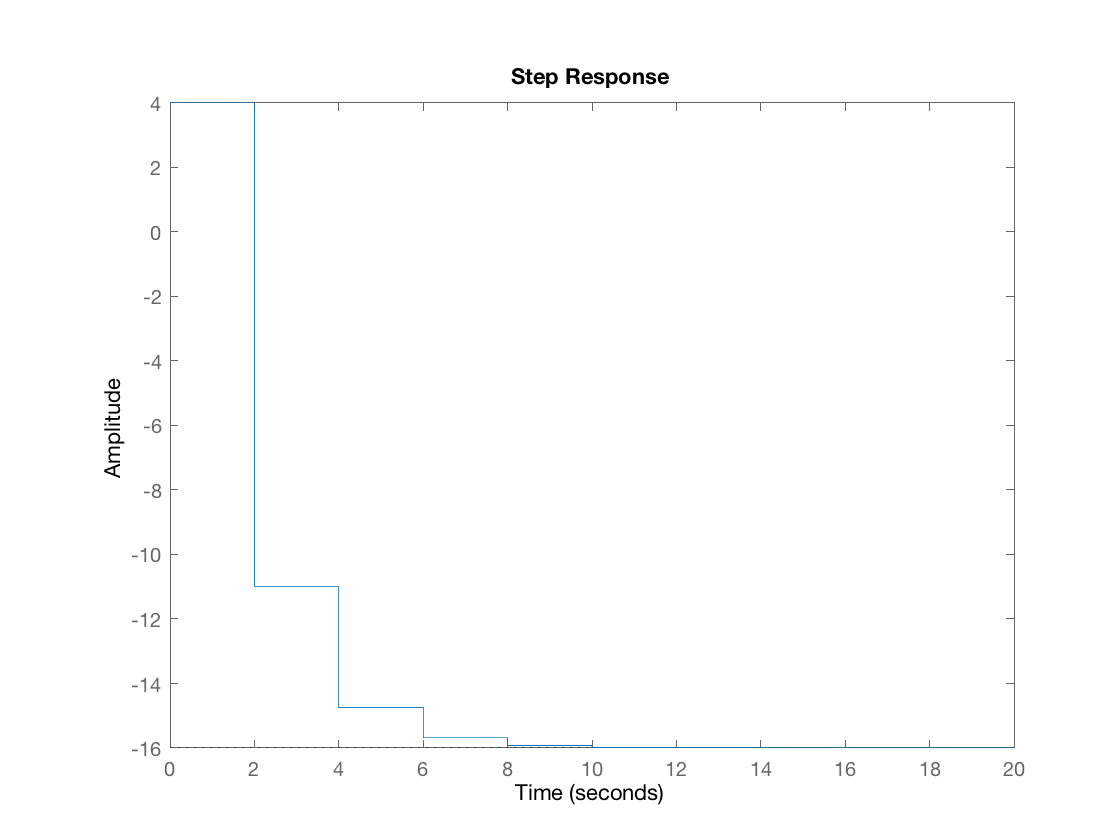

step(H)

What about the sequence?

ys = step(H)

ys =     4.0000
    4.0000
  -11.0000
  -11.0000
  -14.7500
  -14.7500
  -15.6875
  -15.6875
  -15.9219
  -15.9219


%
% Does the sequence match the theory?

## Impulse Response

How about impulse response?

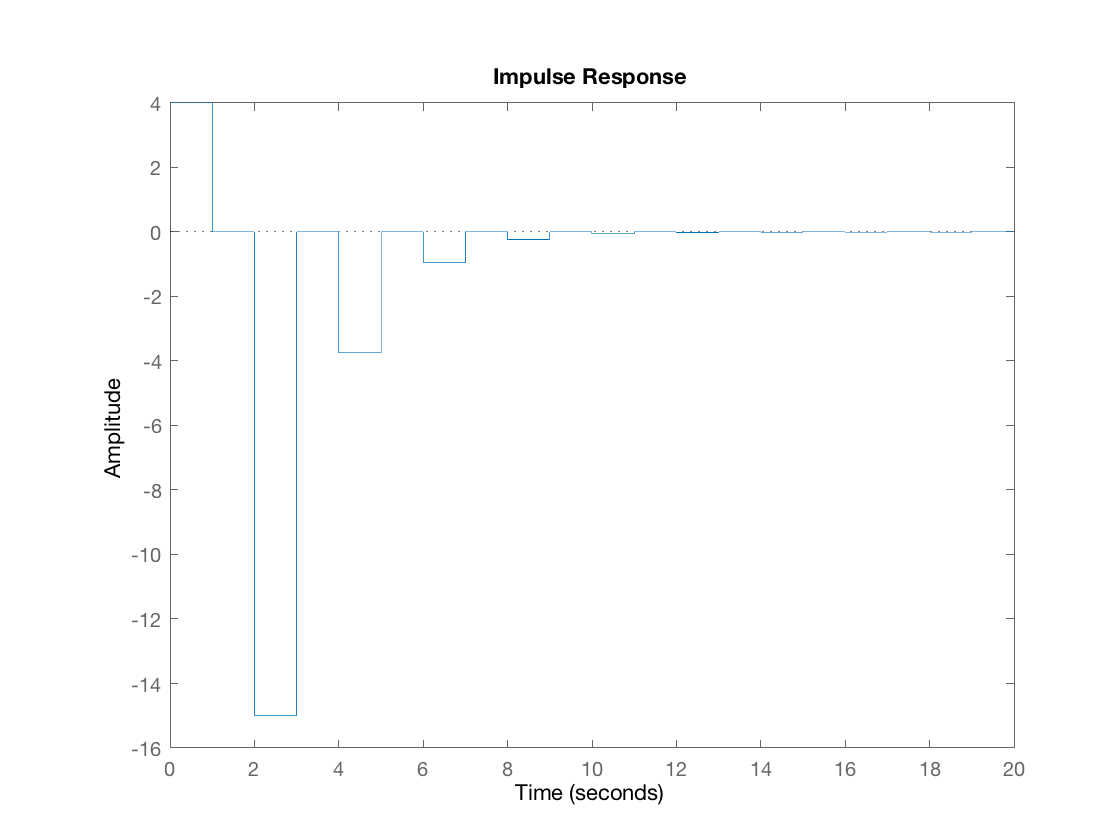

impulse(H)

% The plot isn't quite right -- it's a "hold-equivalent" result.
% We don't know values between sampling instants.

## Sequence?

yi = impulse(H)

yi =     4.0000
         0
  -15.0000
         0
   -3.7500
         0
   -0.9375
         0
   -0.2344
         0


## Stem plot

To plot this properly, we use a stem plot

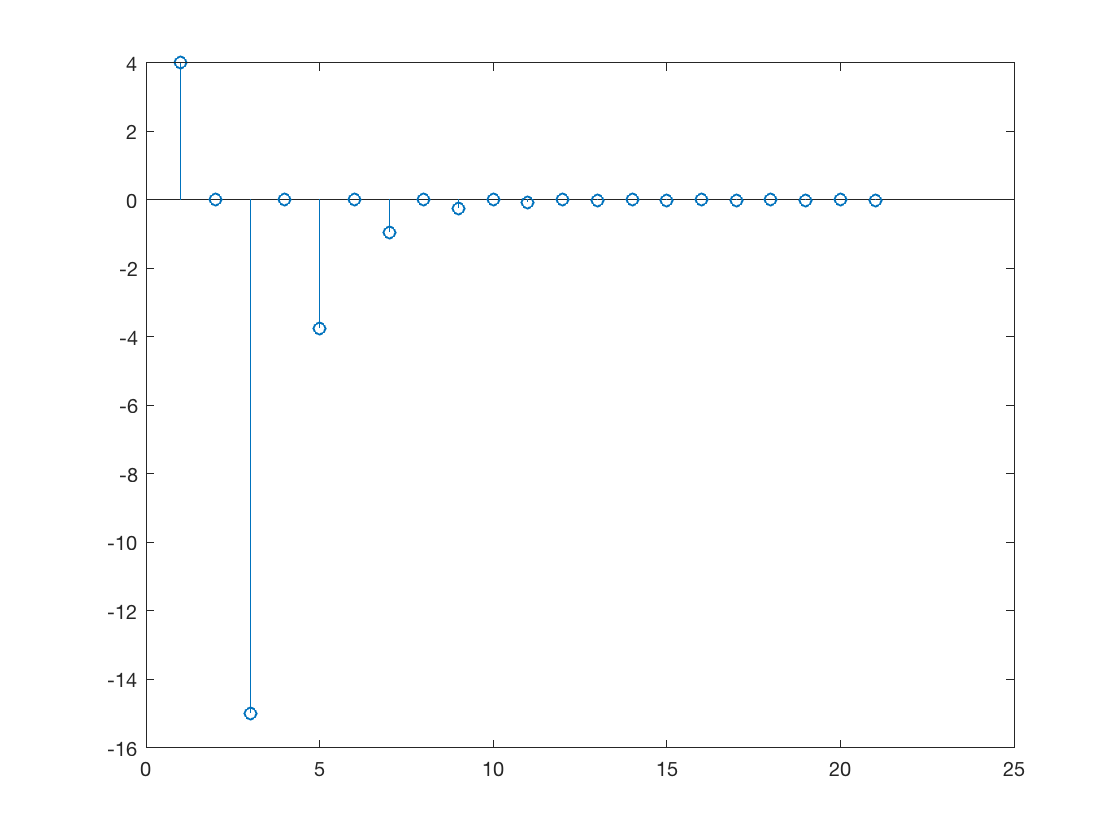

stem(yi)

## Step response as stem plot

Should do same for step response too

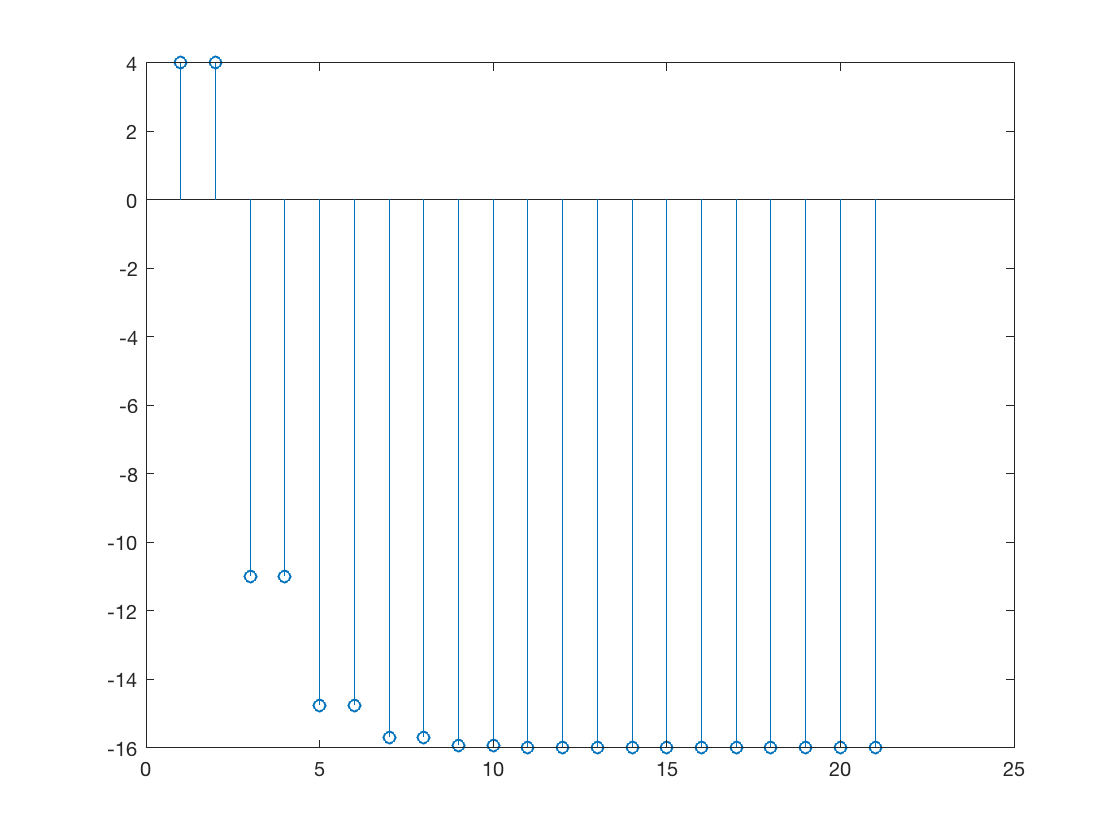

stem(ys)

## Partial fractions

Can we use partial fractions for inverse z transforms?

help residue

 residue Partial-fraction expansion (residues).
    [R,P,K] = residue(B,A) finds the residues, poles and direct term of
    a partial fraction expansion of the ratio of two polynomials B(s)/A(s).
    If there are no multiple roots,
       B(s)       R(1)       R(2)             R(n)
       ----  =  -------- + -------- + ... + -------- + K(s)
       A(s)     s - P(1)   s - P(2)         s - P(n)
    Vectors B and A specify the coefficients of the numerator and
    denominator polynomials in descending powers of s.  The residues
    are returned in the column vector R, the pole locations in column
    vector P, and the direct terms in row vector K.  The number of
    poles is n = length(A)-1 = length(R) = length(P). The direct term
    coefficient vector is empty if length(B) < length(A), otherwise
    length(K) = length(B)-length(A)+1.
 
    If P(j) = ... = P(j+m-1) is a pole of multplicity m, then the
    expansion includes terms of the form
            

## PFE for for inverse z-transform of impulse response

[r,p,k] = residue([4,0,-16],[1,0,-0.25])

r =    -15
    15


p =     0.5000
   -0.5000


k = 4

## PFE for inverse z-transform for step response

[r,p,k] = residue(conv([1, 0],[4,0,-16]),conv([1, -1],[1,0,-0.25]))

r =   -16.0000
   15.0000
    5.0000


p =     1.0000
    0.5000
   -0.5000


k = 4

%
% Do these results match the theory?

## Another approach

Use LTI block to define the TF then extract num/den for PFE

U = tf([1, 0], [1, -1], -1)


U =
 
    z
  -----
  z - 1
 
Sample time: unspecified
Discrete-time transfer function.



Y = series(U, H)


Y =
 
        4 z^3 - 16 z
  -------------------------
  z^3 - z^2 - 0.25 z + 0.25
 
Sample time: unspecified
Discrete-time transfer function.



% extract numerator & denominator
[num,den] = tfdata(Y,'v')

num =      4     0   -16     0


den =     1.0000   -1.0000   -0.2500    0.2500


% get pfe
[r,p,k]=residue(num,den)

r =   -16.0000
   15.0000
    5.0000


p =     1.0000
    0.5000
   -0.5000


k = 4